# Projeto final ES728 - Problema do Carro pêndulo

Alunos:

- Bruno Monteiro Bonetti - 232488 

- Luis Paulo Siqueira Silva - 183045

## Introdução

Este relatório aborda o estudo e desenvolvimento de soluções de controle aplicadas ao sistema de pêndulo sobre carrinho, uma configuração clássica na teoria de controle e dinâmica. Este sistema, amplamente utilizado como referência para testes de algoritmos de controle, combina desafios teóricos e práticos, tornando-se ideal para a aplicação de ferramentas como MATLAB e SIMULINK.

Ao longo do trabalho, são analisadas diversas etapas do processo de estabilização do sistema linearizado, incluindo a criação de modelos de espaço de estados, projeto de controladores, análise de estabilidade e implementação de observadores de estado. Além disso, também são exploradas as particularidades do comportamento do sistema não linear.

As tarefas descritas no relatório seguem uma abordagem progressiva, começando com a modelagem e análise básica, até alcançar o projeto de controladores mais sofisticados, como controladores LQR e observadores de estado. A aplicação prática dessas técnicas é realizada por meio de simulações, cujos resultados são discutidos de forma a garantir o entendimento das limitações e potencialidades das metodologias empregadas.

## Modelagem - Questão 1.1

Primeiramente, é necessário modelarmos o sistema que possuímos para poder começar a trabalhar e aplicar tudo o que precismos no Matlab, dessa forma, utilizando o código evidenciado abaixo temos que a modelagem do sistema pode ser encontrada.

clc; close all; clear all;

mc = 1.5; % mass of the cart
mp = 0.5; % mass of the pendulum
g = 9.82; % gravity
L = 1;    % length of the pendulum
d1 = 1e-2;  % damping of the cart displacement
d2 = 1e-2; % damping of the joint

A = [0,   0,   1,    0;
    0,   0,   0,    1;
    0,   g*mp/mc,   -d1/mc, -d2/(L*mc);
    0,   g*(mc+mp)/(L*mc),  -d1/(L*mc), -d2*(mc+mp)/(L^2*mc*mp)];

A =          0         0    1.0000         0
         0         0         0    1.0000
         0    3.2733   -0.0067   -0.0067
         0   13.0933   -0.0067   -0.0267



B = [ 0; 0; 1/mc;  1/(L*mc)];

C = [0 1 0 0];

D = 0;

C_q1 = [1 0 0 0];

sys = ss(A, B, C, D)


sys =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3          0      3.273  -0.006667  -0.006667
   x4          0      13.09  -0.006667   -0.02667
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


Para esse ponto, estamos considerando $q_2$ como sendo a saída do sistema, como pode-se observar na matriz C.

## Análise de estabilidade e Funções de transferência - Questão 1.2

Para podermos fazer a análise da estabilidade do sistema, podemos utilizar as seguintes funções que o Matlab nos ofere, sabendo que o comando "pole" nos fornece os polos da equação em questão, assim como "eig" retorna os autovalores e, por fim, "zero" nos fornece todos os zeros que o sistema possui. 

poles = pole(sys)
eigenvalues = eig(A)
zeros_ss = zero(sys)

A partir desses resultados temos que o sistema não é estável, uma vez que existe um polo maior do que zero, ou seja, o polo está no semi plano direito ao eixo imáginário, evidenciando um sistema não estável. Ademais, podemos encontrar a função de transferência para o sistema.

[b, a] = ss2tf(A, B, C, D);
ft_q2 = tf(b, a)


ft_q2 =
 
    0.6667 s^2 + 2.333e-17 s + 3.186e-16
  -----------------------------------------
  s^4 + 0.03333 s^3 - 13.09 s^2 - 0.06547 s
 
Continuous-time transfer function.
Model Properties


Essa é a função de transferência original do sistema, sem fazer nenhuma modificação na equação obtida. Porém, faremos o cancelamento de polos e zeros porque a simplificação considerou que os efeitos desses termos insignificantes (em magnitude) podem ser ignorados sem alterar significativamente o comportamento dinâmico do sistema. Ou seja, qualquer número menor que 0.01 será aproximado para zero. Isso resulta em uma função de transferência mais simples, mas que mantém as características essenciais do sistema em frequências relevantes.

[zeros_ss, poles, gain] = zpkdata(ft_q2, 'v');

zeros_ss(abs(zeros_ss) < 1e-2) = 0;
poles(abs(poles) < 1e-2) = 0;

new_tf = zpk(zeros_ss, poles, gain);
new_tf = tf(new_tf)


new_tf =
 
           0.6667 s^2
  -----------------------------
  s^4 + 0.02833 s^3 - 13.09 s^2
 
Continuous-time transfer function.
Model Properties


Essa função encontrada pode ser simplificada:

simplified_new_tf = minreal(new_tf)


simplified_new_tf =
 
          0.6667
  -----------------------
  s^2 + 0.02833 s - 13.09
 
Continuous-time transfer function.
Model Properties


[zeros_ss, poles, gain] = zpkdata(simplified_new_tf, 'v');

Logo, essa é a função de transferência simplificada encontrada para quando aproximamos os polos e zeros próximos de zero para zero.

## Função de transferência para saída q1 - Questão 1.3

A função de transferência para a saída q2 já foi mostrada no item anterior e será usada nesse relatório. Além disso, para uma saída q1, podemos alterar a matriz C, de modo que altere a saída do sistema de q2 para q1. Assim, podemos, também, gerar uma função de transferência para essa nova saída. Essa função está apresentada abaixo:

[b_q1, a_q1] = ss2tf(A, B, C_q1, D);
ft_q1 = tf(b_q1, a_q1)


ft_q1 =
 
       0.6667 s^2 + 0.01333 s - 6.547
  -----------------------------------------
  s^4 + 0.03333 s^3 - 13.09 s^2 - 0.06547 s
 
Continuous-time transfer function.
Model Properties


Assim como a função para a saída q2 como já havia sido mostrada:

ft_q2


ft_q2 =
 
    0.6667 s^2 + 2.333e-17 s + 3.186e-16
  -----------------------------------------
  s^4 + 0.03333 s^3 - 13.09 s^2 - 0.06547 s
 
Continuous-time transfer function.
Model Properties


## Comparação - Questão 1.4

Através da função de transferência ft_q1, que diz respeito a saída q1 do sistema, e usando a função zpkdata do Matlab, é possível encontrar os zeros, polos e ganhos da função. Assim, temos que:

[zeros_ss, poles, gain] = zpkdata(ft_q1, 'v')

zeros_ss =    -3.1437
    3.1237


poles =          0
   -3.6327
    3.6043
   -0.0050


gain = 0.6667

O mesmo pode ser feito para a função ft_q2, que diz respeito a saída q2:

[zeros_ss, poles, gain] = zpkdata(ft_q2, 'v')

zeros_ss = 1.0e-07 *

  -0.0000 + 0.2186i
  -0.0000 - 0.2186i


poles =          0
   -3.6327
    3.6043
   -0.0050


gain = 0.6667

A partir de uma análise em cima desses resiultados, podemos ver que os polos são iguais pois dependem apenas da matriz A, como podemos ver no denominador da equação de função de transferencia a partir do espaço de estados:

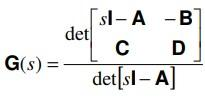

Já os zeros, dependerm de todas as matrizes, como se pode ver no numerador da mesma equação. Assim, variando C, varia-se os zeros da função. Por conta disso, os polos são iguais para ambas, porém os zeros variam.

## Questão 2.1

Usando os valores passados das matrizes A, B, C, D, construimos o seguinte no Simulink:

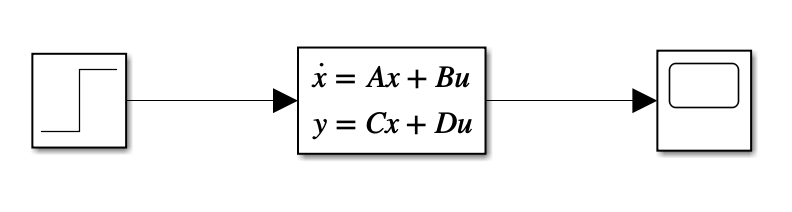

Plotando a resposta ao degrau, obtemos o seguinte:

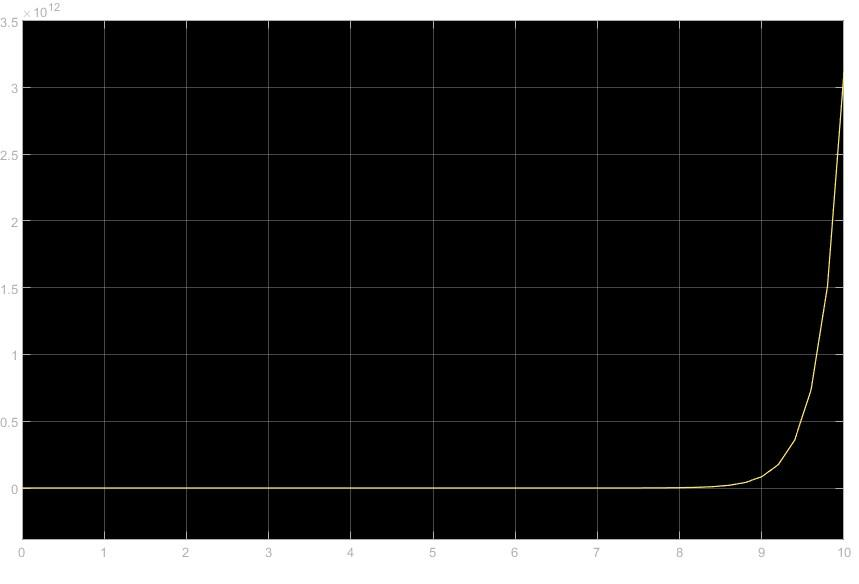

Verifica-se que o sistema é instável, com sua amplitude de resposta tendendo ao infinito.

## Questão 2.2

% rlocus(ft_q2)
% grid on;
% 
% rlocus(simplified_new_tf)
% grid on;

Com o plot do lugar das raízes das duas funções de tranferência (a primeira sendo o sistema original, e a segunda sendo a função em que primeiro aproximamos para zero os polos e zeros, e depois fizemos o cancelamento), fica notável a diferença entre as duas. Na primeira, temos mais polos e zeros, enquanto que na segunda eles foram reduzidos mas permanecem no semiplano direito. 

Quanto à capacidade de um controlador P estabilizar a malha fechada, o grupo entende que não é possível pois os polos se encontram no semiplano direito, o que já indica instabilidade. O lugar das raízes indica que, para K>0, os polos dominantes permanecem no semiplano direito. Assim, um controlador proporcional simples P não é suficiente para estabilizar o sistema.

## Questão 2.3

% sisotool(ft_q2)

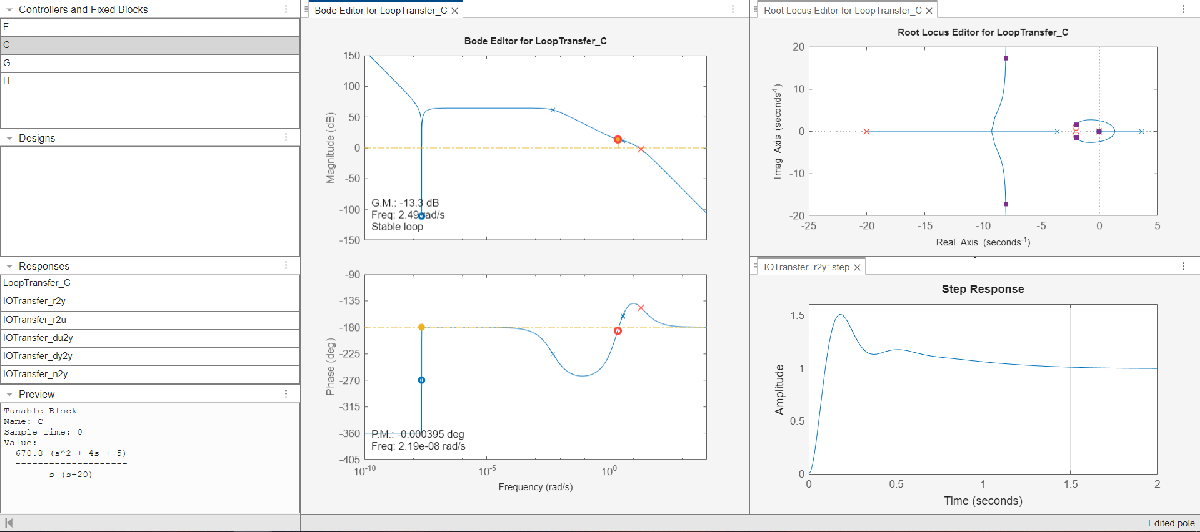

O controlador encontrado tem a seguinte função de transferência:


$$\frac{670.84(s^2 + 4s+5)}{s(s+20)}$$


O ganho estabilizante encontrado foi, portanto, de 670.84.

## Questão 2.4

Exportamos o controlador encontrado no item anterior para o simulink, e obtivemos o seguinte diagrama de blocos:

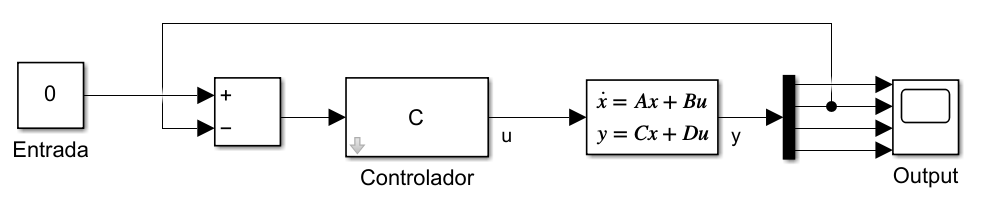

Então, a saída do estado q2 é mostrada abaixo.

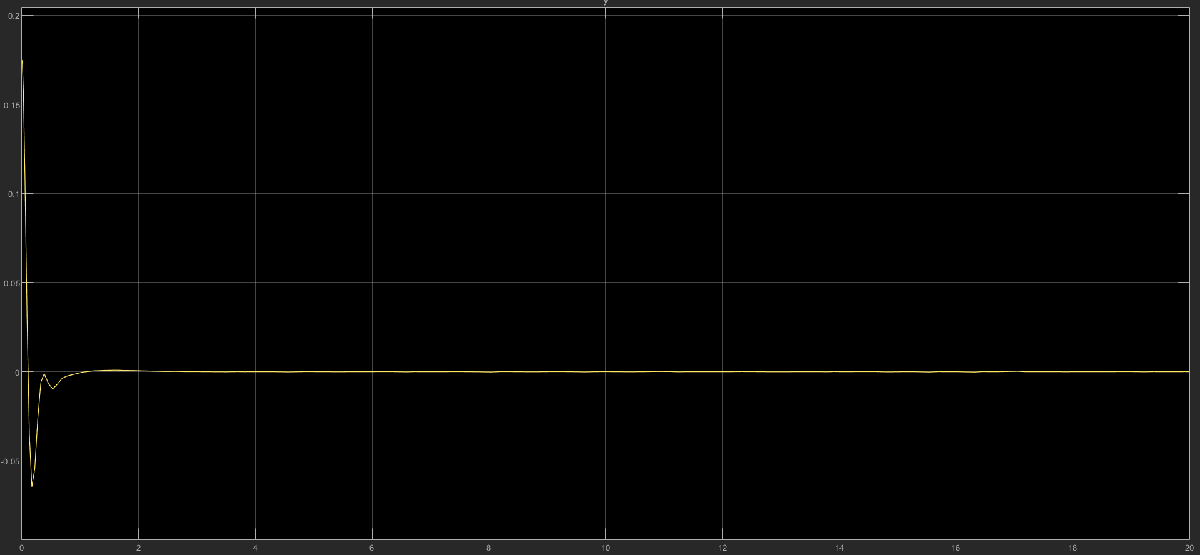

Percebe-se que ela se estabiliza no set point de 0, mesmo com a condição inicial de 0.174533 rad (10°), como era esperado. 

Simulando 100s, obtivemos o seguinte, mostrando todos os estados:

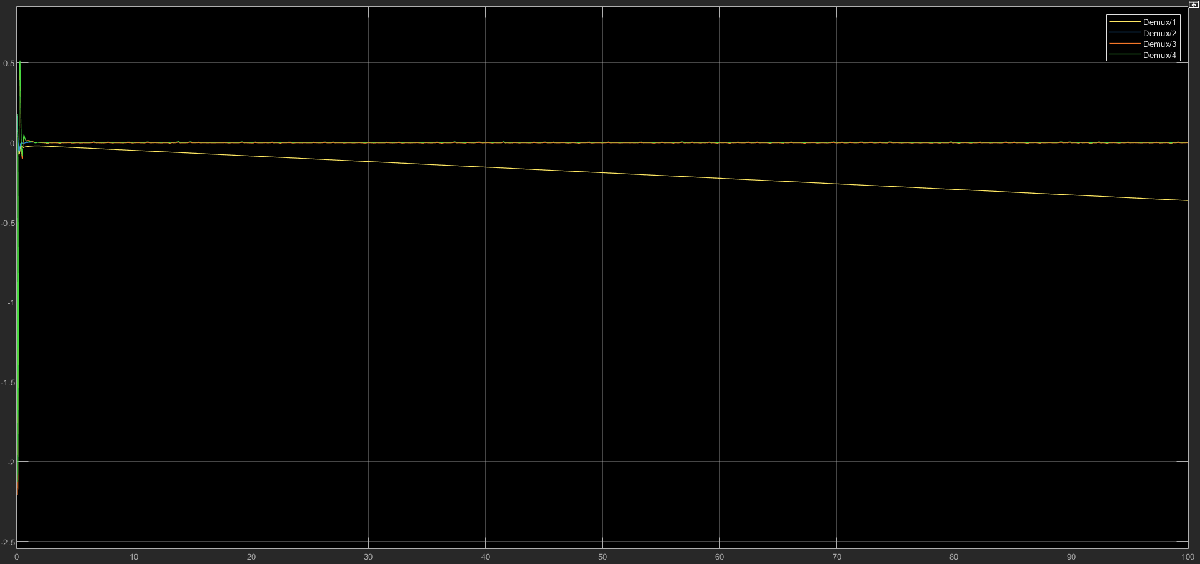

Aqui, observamos que não são todos os estados que convergem para zero. O estado q1 possui um decaimento linear com o passar do tempo, como pode ser visto na figura. Isso se deve por conta de não ter sido realizado o controle sobre a posição do carrinho, que é justamente o estado q1. Para evitar esse problema, basta realizar um controle, de forma similar à realizada para o pêndulo, só que para a posição do carrinho. Dessa forma, o estado q1 passaria a tender a zero também.

## Questão 3.1

cont_q1 = ctrb(A,B)

cont_q1 =          0    0.6667   -0.0089    2.1824
         0    0.6667   -0.0222    8.7295
    0.6667   -0.0089    2.1824   -0.1455
    0.6667   -0.0222    8.7295   -0.5383


rank(cont_q1)

ans = 4


obsv_q1 = obsv(A, C_q1)

obsv_q1 =     1.0000         0         0         0
         0         0    1.0000         0
         0    3.2733   -0.0067   -0.0067
         0   -0.1091    0.0001    3.2736


rank(obsv_q1)

ans = 4

Por possuir o rank cheio, tanto para a controlabilidade quanto para a observabilidade, podemos afirmar que para a saída q1, o sistema é controlável e observável.

cont_q2 = ctrb(A,B)

cont_q2 =          0    0.6667   -0.0089    2.1824
         0    0.6667   -0.0222    8.7295
    0.6667   -0.0089    2.1824   -0.1455
    0.6667   -0.0222    8.7295   -0.5383


rank(cont_q2)

ans = 4


obsv_q2 = obsv(A, C)

obsv_q2 =          0    1.0000         0         0
         0         0         0    1.0000
         0   13.0933   -0.0067   -0.0267
         0   -0.3710    0.0002   13.0941


rank(obsv_q2)

ans = 3

Como a matriz A e B não mudam para a saída q2, o sistema continua sendo controlável. Porém, como a matriz C muda e o número de rank não é cheio, temos que, para essa saída, o sistema não é observável.

## Questão 3.2

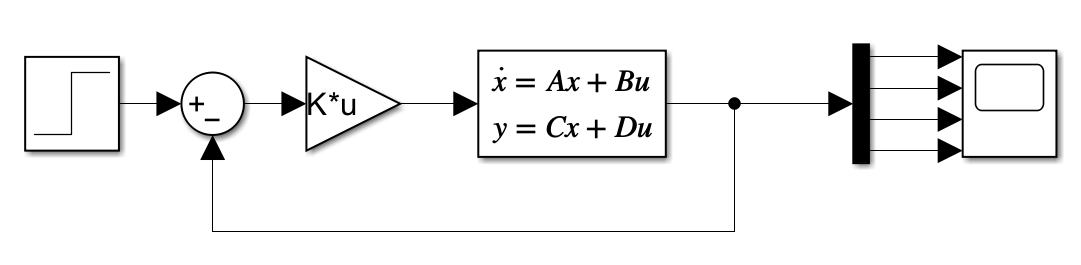

polos_desejados = [-1, -2, -1.5, -3]

polos_desejados =    -1.0000   -2.0000   -1.5000   -3.0000


K = place(A, B, polos_desejados)

K =    -1.3747   51.0835   -3.4497   14.6497


eig(A-B*K)

ans =    -3.0000
   -2.0000
   -1.5000
   -1.0000


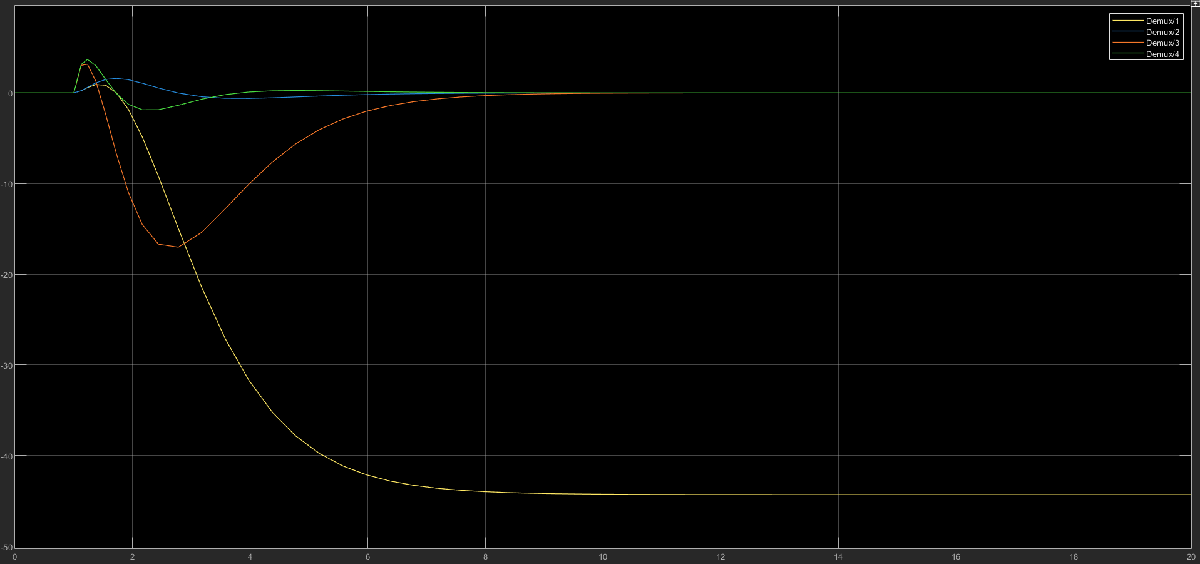

## Questão 3.3

Escolhendo novos polos, agora dois pares complexos, obtemos o seguinte:

polos_desejados2 = [-8-1i, -8+1i, -10-2i, -10+2i];
K2 = place(A,B, polos_desejados2)

K2 = 1.0e+03 *

   -1.0326    1.7948   -0.4549    0.5088


eig(A-B*K2)

ans =  -10.0000 + 2.0000i
 -10.0000 - 2.0000i
  -8.0000 + 1.0000i
  -8.0000 - 1.0000i


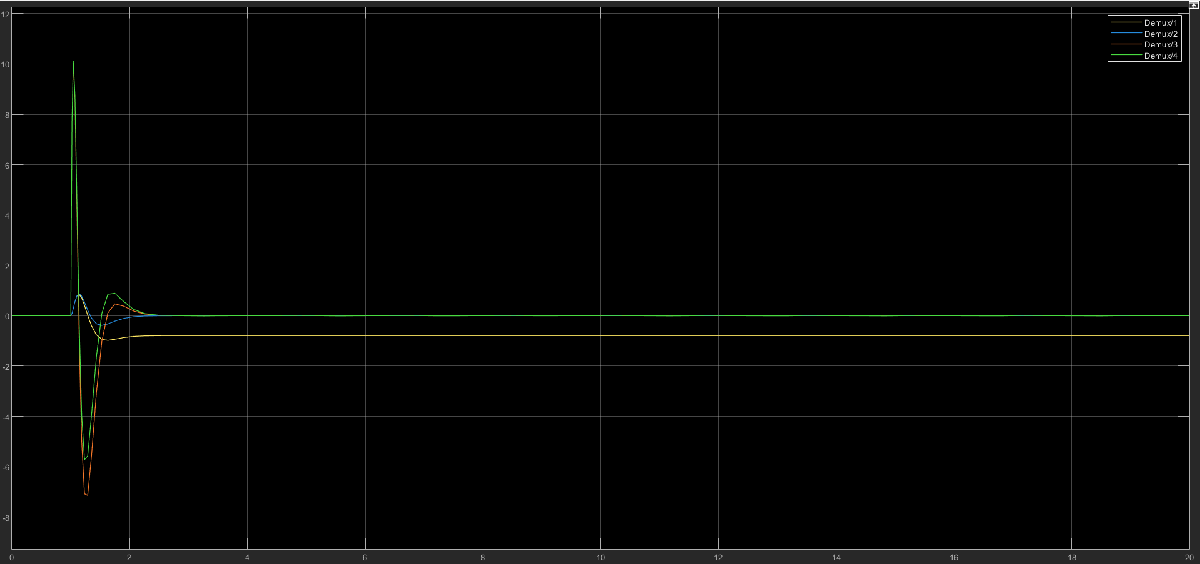

## Questão 3.4

Feito na questao3_4.m e questao3_4_simu.smx de mesmo nome. Podemos mostrar tanto os gráficos feitos pelo professor, quanto o degrau e constante 0 do simulink. Para rodar o simulink, precisa rodar antes o .m . O controlador obtido é o seguinte: 

K =  -10.0000   92.7912  -12.2159   27.9026

Usou-se rho = 100 e R = 1. Depois com o script de normalização, encontrou-se que N_ = -10.

## Questão 3.5

Aqui acredito que basta chutar outros valores de rho. Tem que ser feito.

## Questão 3.6

Colocamos o K do LQR obtido [-9.9999999999996145, 92.791161254939809, -12.215905748548041, 27.902583587911245] no arquivo disponibilizado pelo professor e a faixa de ângulo em que foi possível obter estabilidade no carrinho foi de -0.93 rad (-53,28°) até  0.793 rad (45,435553 °). Os resultados são mostrados a seguir. Vale ressaltar que o vetor de condições iniciais era [0.1, x, 0, 0], sendo 0.1 a posição inicial do carrinho, x o ângulo do pêndulo em que se testou diferentes possibilidades de estabilização, e 0 para velocidade do carrinho e velocidade angular do pêndulo.

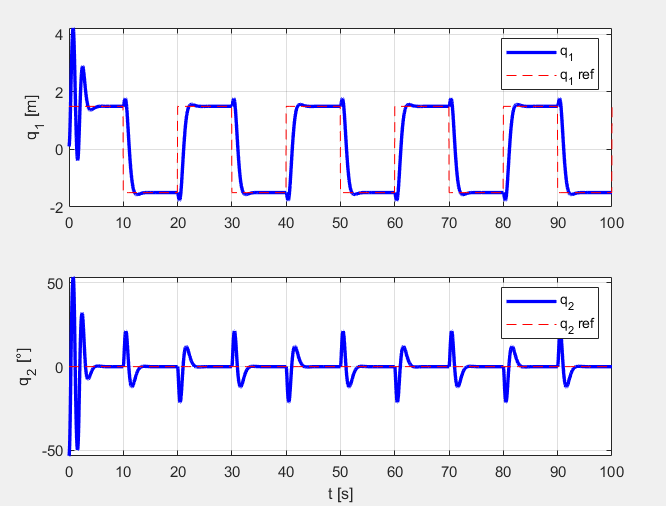

Ângulo inicial de -0.93 rad.

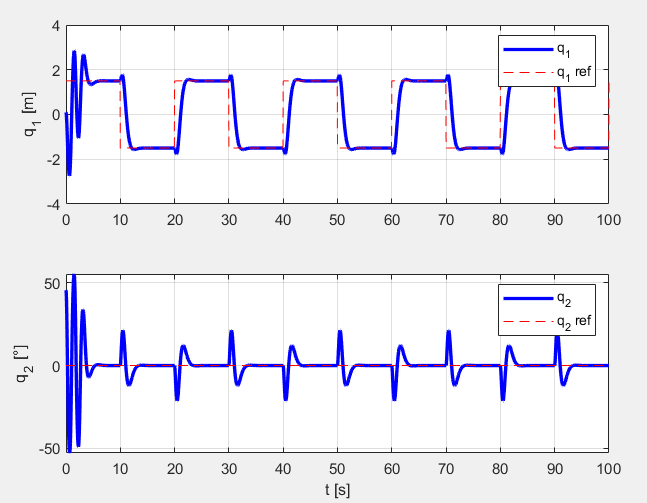

Ângulo inicial de 0.793 rad.

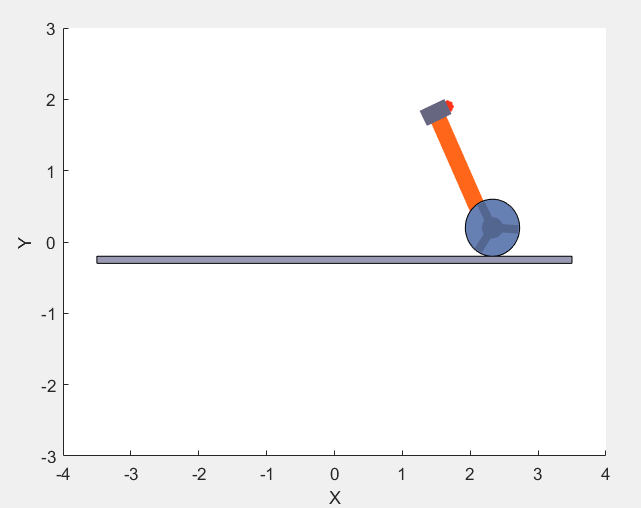

Sistema carro-pêndulo simulado.

## Questão 4

% primeiro, vamos analisar os polos obtidos do controlador LQR para poder
% fazer o observador ainda mais rapido

K_LQR = [-9.9999999999996145, 92.791161254939809, -12.215905748548041, 27.902583587911245];

polos_do_controlador = eig(A-B*K_LQR)

polos_do_controlador =   -3.5382 + 0.2104i
  -3.5382 - 0.2104i
  -1.7073 + 1.5152i
  -1.7073 - 1.5152i



% para que seja mais rapido, multiplicamos por um fator de 10

polos_do_observador = 10*polos_do_controlador

polos_do_observador =  -35.3821 + 2.1042i
 -35.3821 - 2.1042i
 -17.0735 +15.1524i
 -17.0735 -15.1524i



%  como verificado na questao 3, usando a matriz C com a saida q2, nao é
%  observavel, portanto usaremos C_q1

A_observador = A';
B_observador = C_q1';
C_observador = B';
L_observador = polos_do_observador';

L_transposto = acker(A_observador, B_observador, polos_do_observador)

L_transposto = 1.0e+05 *

    0.0010    0.2520    0.0420    2.1682


L = L_transposto'

L = 1.0e+05 *

    0.0010
    0.2520
    0.0420
    2.1682




Nbar = rscale(ss(A, B, C_q1, D),K_LQR)

Nbar = -10.0000


A1 = A - B * K_LQR; 
A2 = B * K_LQR;     
A3 = zeros(size(A)); 
A4 = A - L * C_q1;  

Ace = [A1 A2; 
       A3 A4];

Bce = [B*Nbar;
       zeros(size(B))];

Cn = [1 0 0 0; 0 1 0 0] ;

Cce = [Cn zeros(size(Cn))]

Cce =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0



Dce = [0];

sys_com_observador = ss(Ace, Bce, Cce, Dce)


sys_com_observador =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8
   x1           0           0           1           0           0           0           0           0
   x2           0           0           0           1           0           0           0           0
   x3       6.667      -58.59       8.137      -18.61      -6.667       61.86      -8.144        18.6
   x4       6.667      -48.77       8.137      -18.63      -6.667       61.86      -8.144        18.6
   x5           0           0           0           0      -104.9           0           1           0
   x6           0           0           0           0   -2.52e+04           0           0           1
   x7           0           0           0           0       -4203       3.273   -0.006667   -0.006667
   x8           0           0           0           0  -2.168e+05       13.09   -0.006667    -0.02667
 
  B = 
           u1
   x1       0
   x2       0


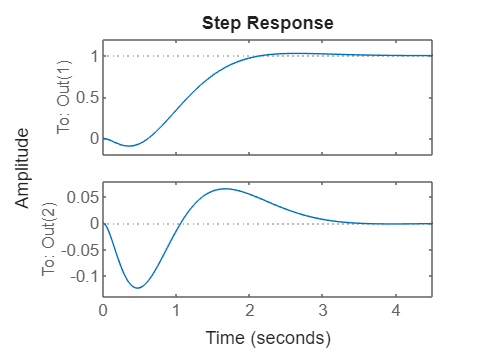


% agora temos 8 estados, 4 originais e 4 do observador

t = 0:0.01:10;
r = ones(size(t));
[y,t,x]=lsim(sys_com_observador,r,t, [0 0 0 0 0 0 0 0]');

step(sys_com_observador)

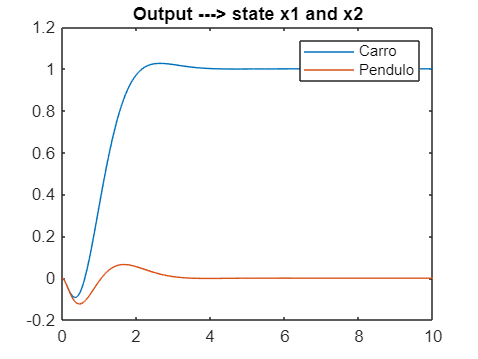


figure(1);
plot(t,y);
title('Output ---> state x1 and x2')
legend("Carro", "Pendulo")

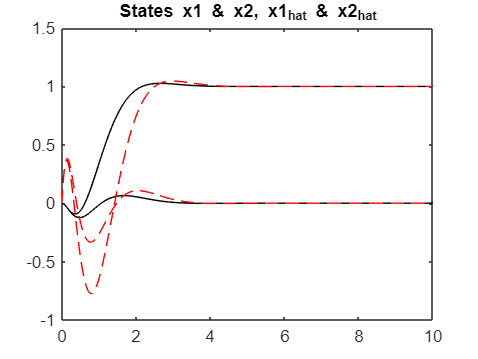


figure(2);
x_hat=-(x(:,3:4)-x(:,1:2));
plot(t,x(:,1:2),'k');
hold on; plot(t,x_hat(:,1:2),'r--')
title('States x1 & x2, x1_{hat} & x2_{hat}')